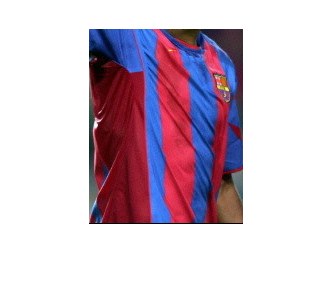

clear all
image=imread('base.jpg');
image=double(image);
figure,imshow(uint8(image))


Image_red = image(:,:,1);
Image_green = image(:,:,2);
Image_blue = image(:,:,3);

[row,col] = size(image(:,:,1));

numBlocks = 4 

numBlocks = 4

rowSize = uint32(row/numBlocks) - 1

rowSize = uint32
48

colSize = uint32(col/numBlocks) - 1

colSize = uint32
38

pixelsBlock = rowSize * colSize

pixelsBlock = uint32
1824


endrow = uint32(row*8)

endrow = uint32
1560

endcol = uint32(col*5)

endcol = uint32
770


redPixels = 0;
bluePixels = 0;
greenPixels = 0;
isBarsa = 0;

for i = 1:numBlocks
    for j = 1:numBlocks
        if (i == 1 && j == 1)
            startrow = j*rowSize - rowSize + 1;
            startcol = i*colSize - colSize + 1;
        else
            if (i == 1)
                startrow = j*rowSize - rowSize;
                startcol = i*colSize - colSize + 1;
            end
            if (j == 1)
                startrow = j*rowSize - rowSize + 1;
                startcol = i*colSize - colSize;
            end
        end
        if ( i ~= 1 && j ~= 1)
            startrow = j*rowSize - rowSize;
            startcol = i*colSize - colSize;
        end
        endrow = startrow + rowSize;
        endcol = startcol + colSize;
        redPixels = 0
        bluePixels = 0
        greenPixels = 0
        for y = startrow:endrow 
            for x = startcol:endcol 
              Red = Image_red(y,x);
              Green = Image_green(y,x);
              Blue = Image_blue(y,x);
              
              if (Red >= 100 && Red <= 150)
                  redPixels = redPixels + 1;
              end
              
              if (Blue >= 30 && Blue <= 60)
                  bluePixels = bluePixels + 1;
              end
            
              NormalizedRed = Red/(Red + Green + Blue);
              NormalizedGreen = Green/(Red + Green + Blue);
              NormalizedBlue = Blue/(Red + Green + Blue);
            
              Image_red(y,x) = NormalizedRed;
              Image_green(y,x) = NormalizedGreen;
              Image_blue(y,x) = NormalizedBlue;
            end
        end
%         Descomentar per veure com genera els blocks
%         image(:,:,1) = Image_red;
%         image(:,:,2) = Image_green;
%         image(:,:,3) = Image_blue;
%         figure; imshow(uint8(255*image));
    end
end

image(:,:,1) = Image_red;
image(:,:,2) = Image_green;
image(:,:,3) = Image_blue;

redPixels

redPixels = 7526

bluePixels

bluePixels = 6596

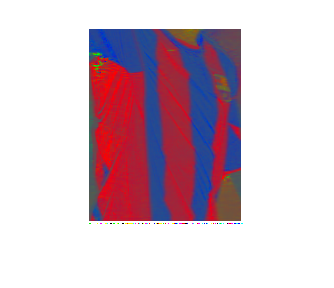


figure; imshow(uint8(255*image));

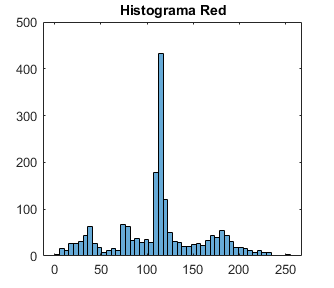


% histogram(image, nBins)
histogram(Image_red(startrow:endrow,startcol:endcol)*255, 50), title('Histograma Red')

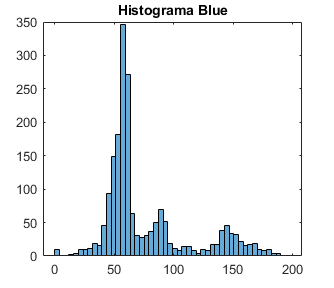

histogram(Image_blue(startrow:endrow,startcol:endcol)*255,50), title('Histograma Blue')

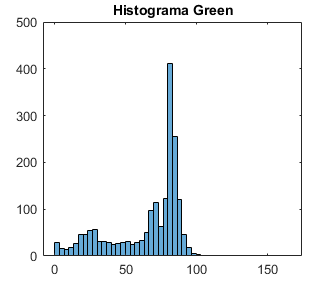

histogram(Image_green(startrow:endrow,startcol:endcol)*255,50), title('Histograma Green')